# Necessary Toolboxes:

- Image processing toolbox

- Statistics and Machine Learning Toolbox

# Necessary packages:

- Install Fast PSF Fitting: [https://github.com/scstein/FastPsfFitting](https://github.com/scstein/FastPsfFitting)

- Install Bio-formats plugin (bfmatlab) [https://docs.openmicroscopy.org/bio-formats/6.3.1/users/matlab/index.html](https://docs.openmicroscopy.org/bio-formats/6.3.1/users/matlab/index.html)

# Add script folder to path:

-  Navigate to photobleach_scripts folder 

- Run the following Command

- Repeat for folder with experimental Data

 

addpath(genpath(pwd))


#  Generate Reference: 

This script will take reference images and identify pairs of molecules in the Cy3 and Cy5 channel to use as a calibration list for transformation of cooridinates between the two channels. 

-  Navigate to 'Ref' folder containing images of reference set

- Run the following script

Generate_reference_set(parms_output_folder_name,parms_output_folder_name,ID_molecules,plot_each_image,last_round_plot,path_to_data);

-  *path_to_data *= give path to folder containing imaging file  Example = 'fit60mer_20240419'

-  *output_name_ID_molecules *= give name for output    Example = 'reference_set_20240419'

- *ID_molecules *= If you have already ID molecules in images do not check this box

- *plot_each_image *= decide if you want to see overlap for each image then check box

- The output from this script is a matlab structure *finalRef*. The structure contains two fields, *finDpt *and *finApt, *with position of reference points in Cy3 and Cy5 channels  



plot_each_image=false;
last_round_plot=true;
ID_molecules=true;
path_to_data='Z:\Loparo Lab\WORKSPACES\Andrew\Single_molecule_data\2024\20240313_invitro_DNAPK_NU7441\Day2\test_analysis';
reference_output_name='reference_20240313';

 

Generate_reference_set(reference_output_name,ID_molecules,plot_each_image,last_round_plot,path_to_data);
clear;

# Generate input parameter file

This method makes a couple of assumptions. First, camera dectector size is 512 X 512 pixels divided equally for Cy3 and Cy5 emission. The Cy3 channel is defined as rows 1:512 and columns 1:256, 

the Cy5 channel is defined as rows 1:512 and columns 257:512. Second, the method assumes alternating excitation between Cy3 excitation and Cy5 excitation. To assign the number of frames in a period adjust the following variables: 

- *number_cy3_excitation_frames* = Define number of Cy3 excitation frames in a period 

- *number_cy5_excitation_frames* = Define number of Cy3 excitation frames in a period 

The total time for each frame is defined in terms of exposure time and delay time between between exposure.

- *exposuret* = time of laser exposure and integration time given in seconds. Example 500 ms integration time   exposuret = 0.5

- *delay* = time of delay between laser exposure Example 500 ms delay   delay = 0.5

The movieframe to start analyzing is defined in terms of Cy3 excitation frame  (*starting_frame)*

- Open imageJ and determine first Cy3 exctitation frame to assign as the start of movie and set *starting_frame *variable.

- start_of_movie = frame number for Cy3 exctitation to start analysis   Example first Cy3 frame for analysis is 22   start_of_movie = 22

- end_of_movie = frame number for last frame to analyze  Example last Cy5 frame for analysis is 546   end_of_movie = 546

- *parms_output_folder_name = *provide a folder name of the parmeter input folder. This folder will store parms_in.txt file and information related to the integrated segments for the movie

There are a number of other parameters that are generated for the parms_in.txt file these parameters can be adjusted either in the script *generate_parms* or can be adjusted in generated *parms_in.txt* file. 

Run the following script: generate_parms(number_cy3_excitation_frames,number_cy5_excitation_frames,exposuret,delay,starting_frame,parms_output_folder_name);

number_cy3_excitation_frames = 1;
number_cy5_excitation_frames = 9;
exposuret = 0.2;
delay = 1;
start_of_movie = 22;
end_of_movie = 546;
parms_output_folder_name='Segments';
 
generate_parms(number_cy3_excitation_frames,number_cy5_excitation_frames,exposuret,delay,start_of_movie,end_of_movie,parms_output_folder_name);
clear;


# Identify tethered molecules, determine drift correction, and integrate molecule intentisy frame by frame: 

**Define input and output name for data integration**

- *input_name_data_integration *= give name of movie   Example = 'Data1.cxd'

- *output_name_data_integration *= give name for output folder   Example = 'Integrated_data'

- *parms_output_folder_name = *provide a folder name of the parmeter input folder. This folder contains the parms_in.txt file and will store information related to the movie integrated segments.

- *name_reference_file = *provide name of reference file located in the movie folder. The reference file is generated in the Generate Reference section and filename is defined with *reference_output_name* variable

 Run the following script  

The initial part of this script will plot the intensity correlation between periods of Cy3 emission. In the figure the dashed black horizontal line denotes a "threshold" for change in Cy3 intensity between periods, the 

vertical green line indicates first cy3 frame of movie and vertical red line indicates last frame of movie. A dialog box is used to define the number of FOV, initial Cy3 frame, and last frame of movie.

After assigning FOV number, position the cursor at the start of first FOV and right click on the mouse. Next position the cursor at the end of the FOV and right click with the cursor. Repeat marking the 

start and stop of each FOV. After marking the last stop point, a new figure will appear indicating start of FOV with green vertical lines and stop of FOV as red vertical lines, if the assignment is correct click true

or if it is wrong click false and the above process will repeat. The FOVs start and stop define the segments of the movie.

If you have already assigned the number of FOV and marked the start and stop of each FOV, you can skip this step by checking the *Already_marked_FOV * box

For each segment, the script will average initial frames, the variable *number_of_frames_to_average* from parms_in.txt defines number of frames to average, then identify the position, regions of interest (roi), of fluorescent molecules 

in the Cy3 channel and curate the list based on intensity, size, and relative position to other molecules. Next, the script will use the reference set to determine the position of fluorescent molecules in the Cy5 channel. 

The script will then determine the drift in x and y cooridinates during imaging of the segment and roi containing no fluorescent molecules in the Cy3 channel (dark_roi) to determine non-specific binding to the coverslip. 

Finally, for each image the script will determine if cy3 or cy5 emission image and calculate the integrated intensity for all roi in that channel. The ouput is provided as a matlab structure containing intensity, position, and size for Cy3 and Cy5 molecules. 

input_name_data_integration = 'Data1.cxd';
output_name_data_integration = 'Integrated_dataB';
parms_output_folder_name = 'Segments';
name_reference_file = 'reference_20240313';
Already_marked_FOV = true;

 
if Already_marked_FOV==true
    define_movie_segments(parms_output_folder_name,output_name_data_integration,input_name_data_integration,name_reference_file,'Segments','Segments');
else
    define_movie_segments(parms_output_folder_name,output_name_data_integration,input_name_data_integration,name_reference_file);
end

#  Identify photobleaching events: 

- To identify photobleaching events launch the GUI *ScanForBleach *by clicking the run button below

- The *ScanForBleach *GUI opens as shown below:

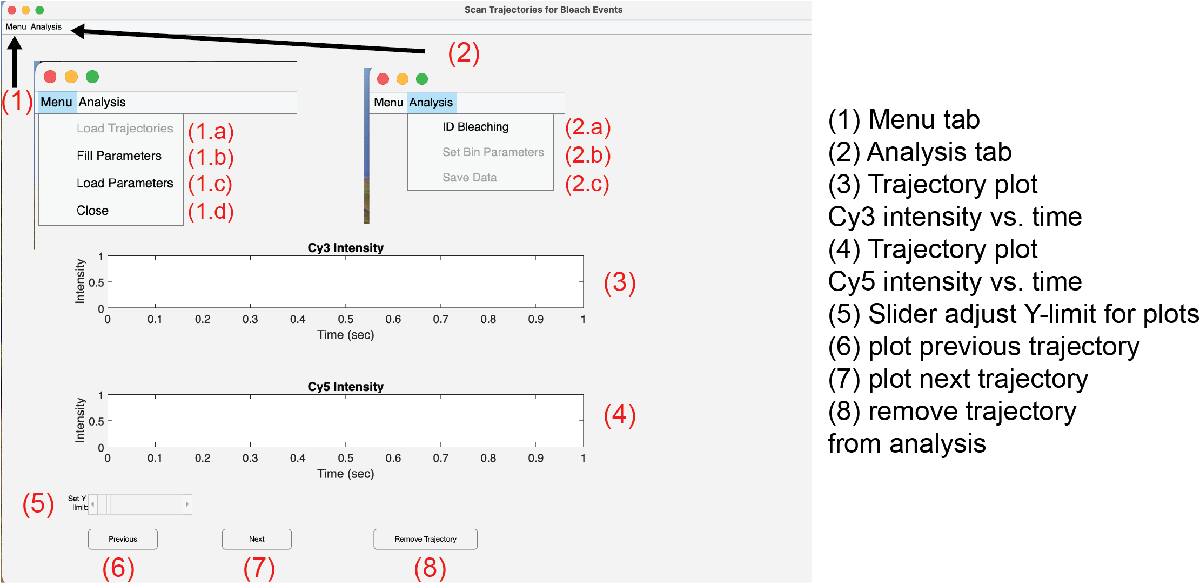

- The first step is to either fill out parameters by clicking (1.b) or loading parameters.txt file by clicking (1.c)

- By clicking the Fill Parameters a window will open to set the parameters. Default values are shown in the editable boxes 

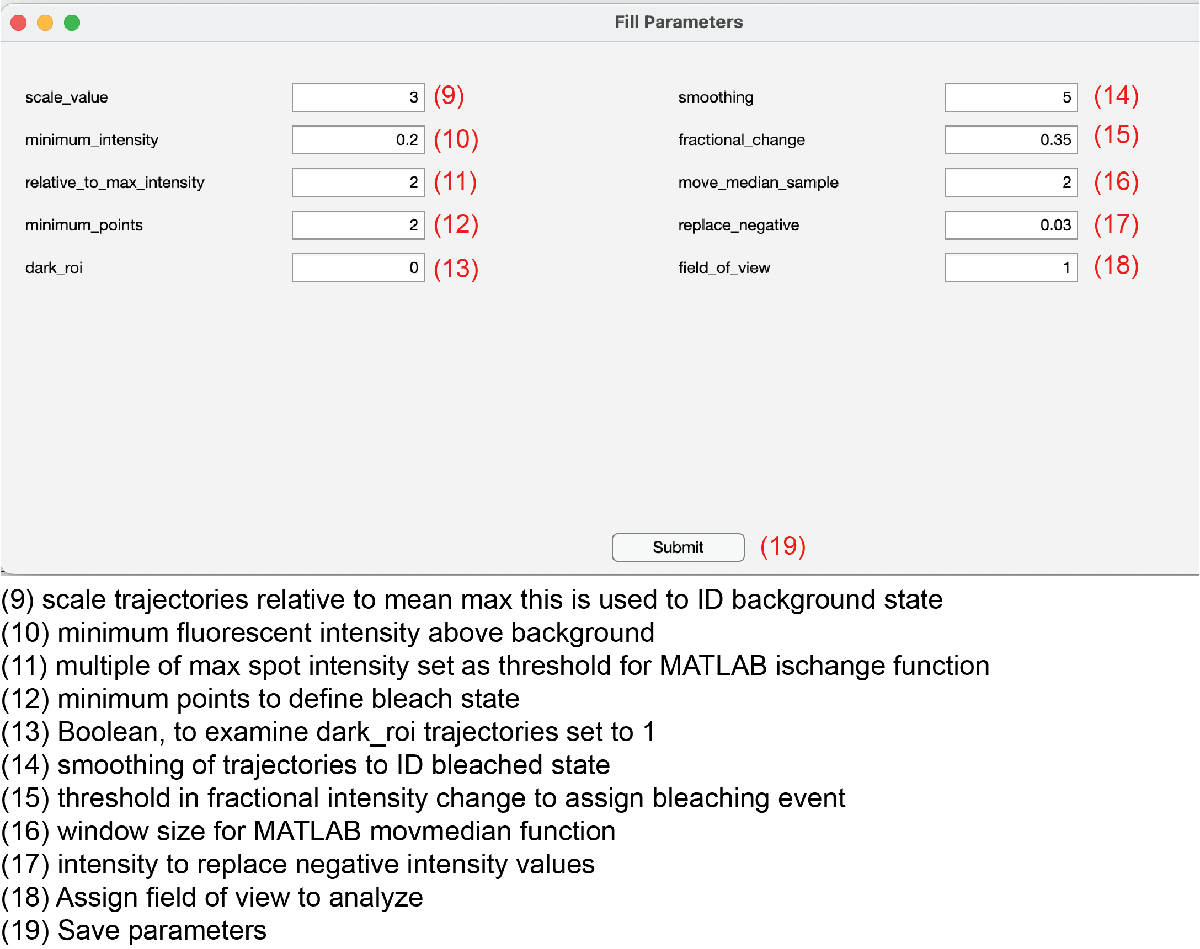

- After assigning and saving parameters file (click submit (19)), this can be loaded again using the load parameters (1.c) from menu tab, the next step is to load the trajectories by clicking Load Trajectories (1.a) from the menu tab and navigating to and selecting integrated data .mat file from the* Identify tethered molecules, determine drift correction, and integrate molecule intentisy frame by frame section.*

- After loading the integrated data you can view individual trajectories and remove trajectories from analysis by clicking remove trajectory (8) while the trajectory is visible

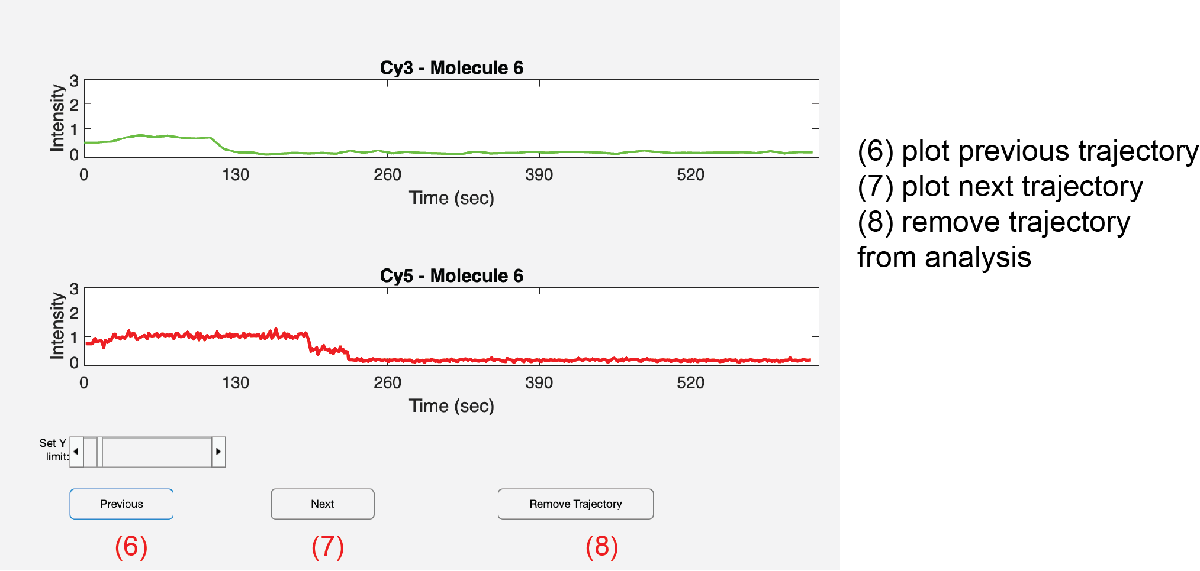

- Next assign photobleaching events by clicking ID Bleaching (2.a). After assigning bleaching events you can view bleaching events and distributions by clicking Previous (6) or Next (7) on the main GUI 

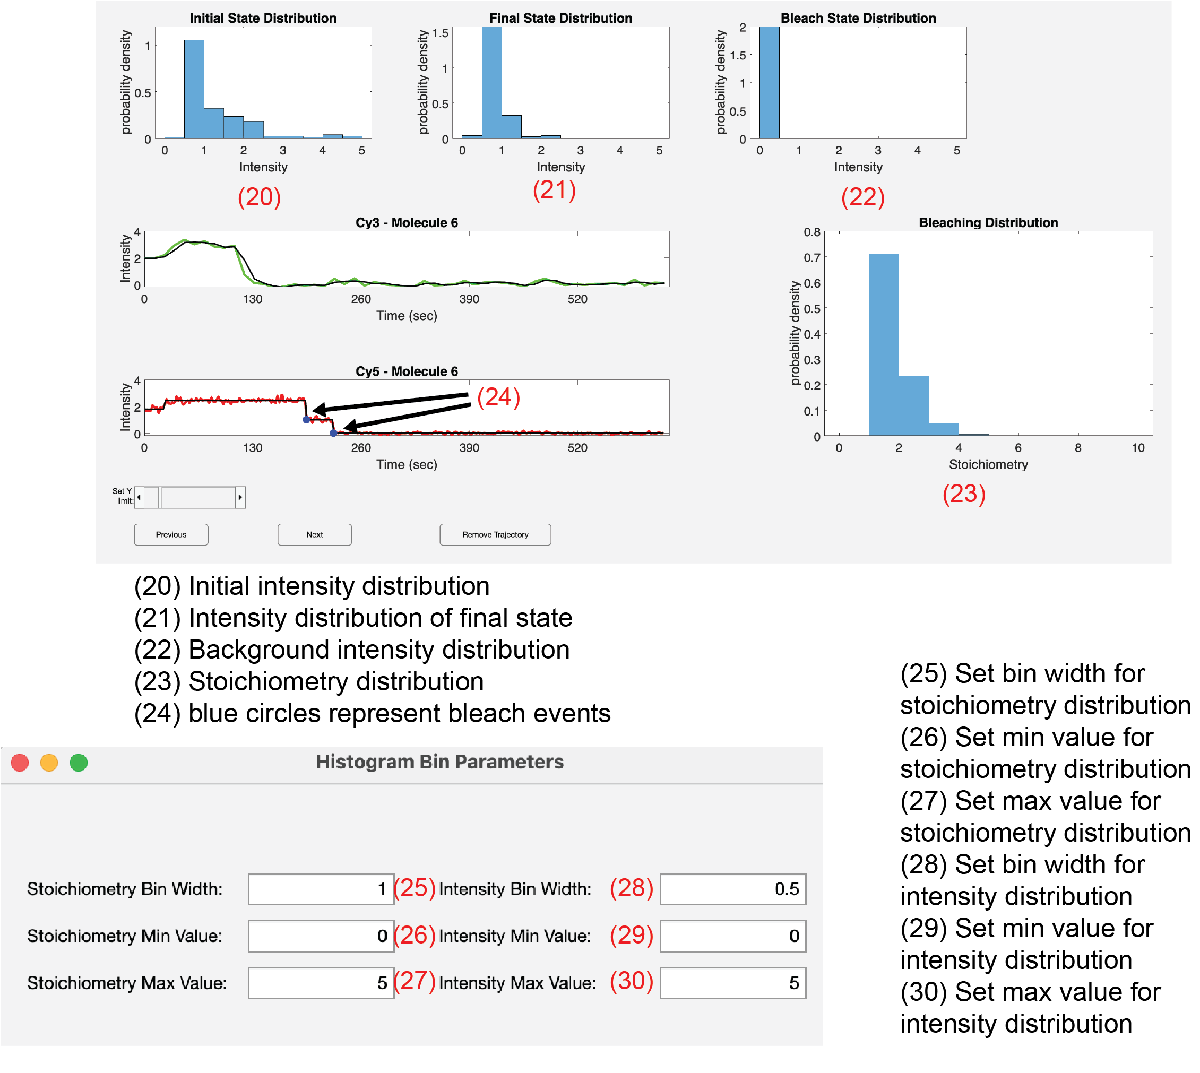

- The histogram bin parameters can be adjusted by clicking Set Bin Parameters (2.b) from the Analysis tab (2). After analyzing photobleaching events click Save (2.c) to save the .mat analysis file and export a .CSV  file with rows conainting bleaching events, initial intensity, final intensity, and background intensity.

- The non-specific binding trajectories can be visualized by setting dark_roi (13) in the parameters GUI to 1.

 
clf;
launch_scanforbleach();
